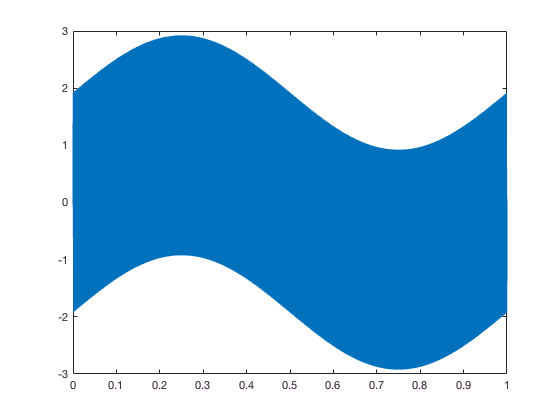

%generate a 100hz sin signal
fs = 8000;
t = 0:1/8000:1;
x = sin(2*pi*1*t)+sin(2*pi*500*t)+sin(2*pi*2000*t);
plot(t,x);

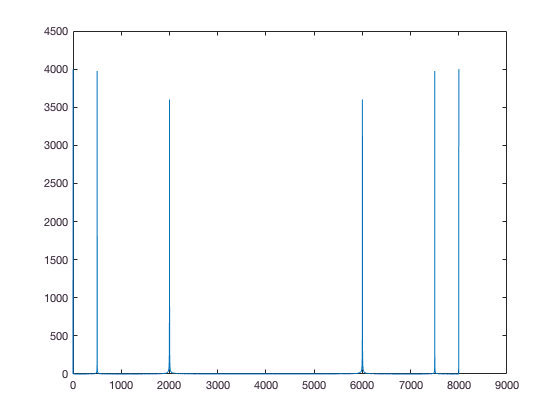

y = fft(x);
plot(abs(y));

load G;
load SOS;
%[s,w] = freqz(SOS(1:3),SOS(4:6));
%plot(abs(s));

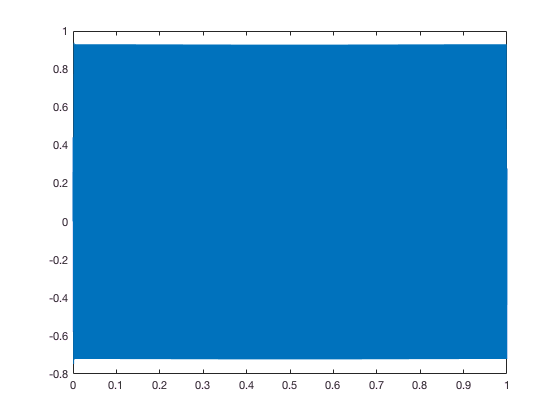

result = zeros(1,8001);
b = SOS(1:3);
a = SOS(4:6);
for i=1:8001
    temp = 0;
    for j = 1:3
        if (i-j+1)>0
            tempX = G(1)*x(i-j+1);
        else
            tempX = 0;
        end
        temp = temp + b(j) * tempX;
    end
    for j = 2:3
        if (i-j+1)>0
            tempX = result(i-j+1);
        else
            tempX = 0;
        end
        temp = temp - a(j) * tempX;
    end
    result(i) = temp;
end
plot(t,result);

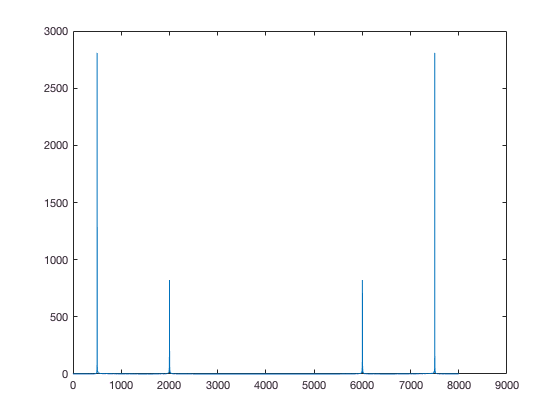

plot(abs(fft(result)));